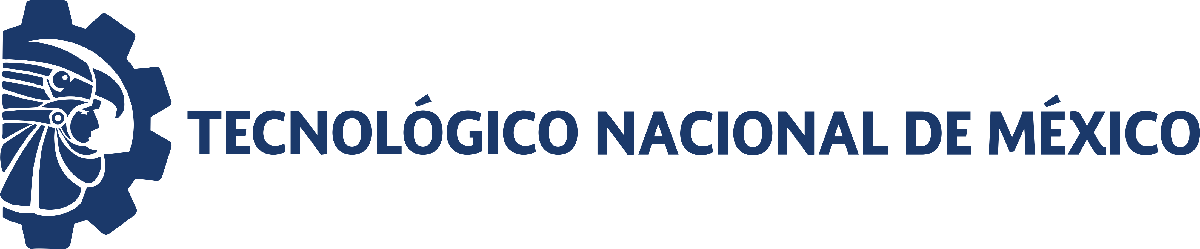                                 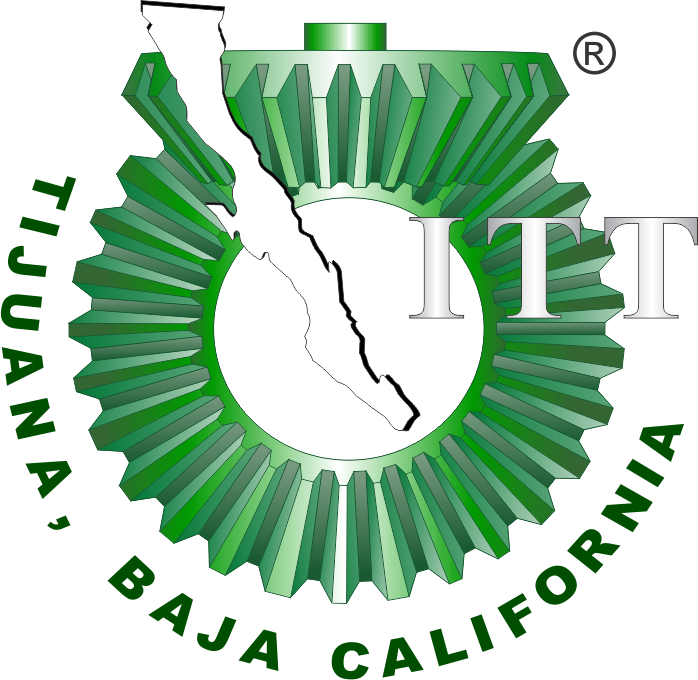

# Práctica 2 — Modelado y control del sistema cardiovascular mediante el modelo Windkessel de cuatro elementos

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

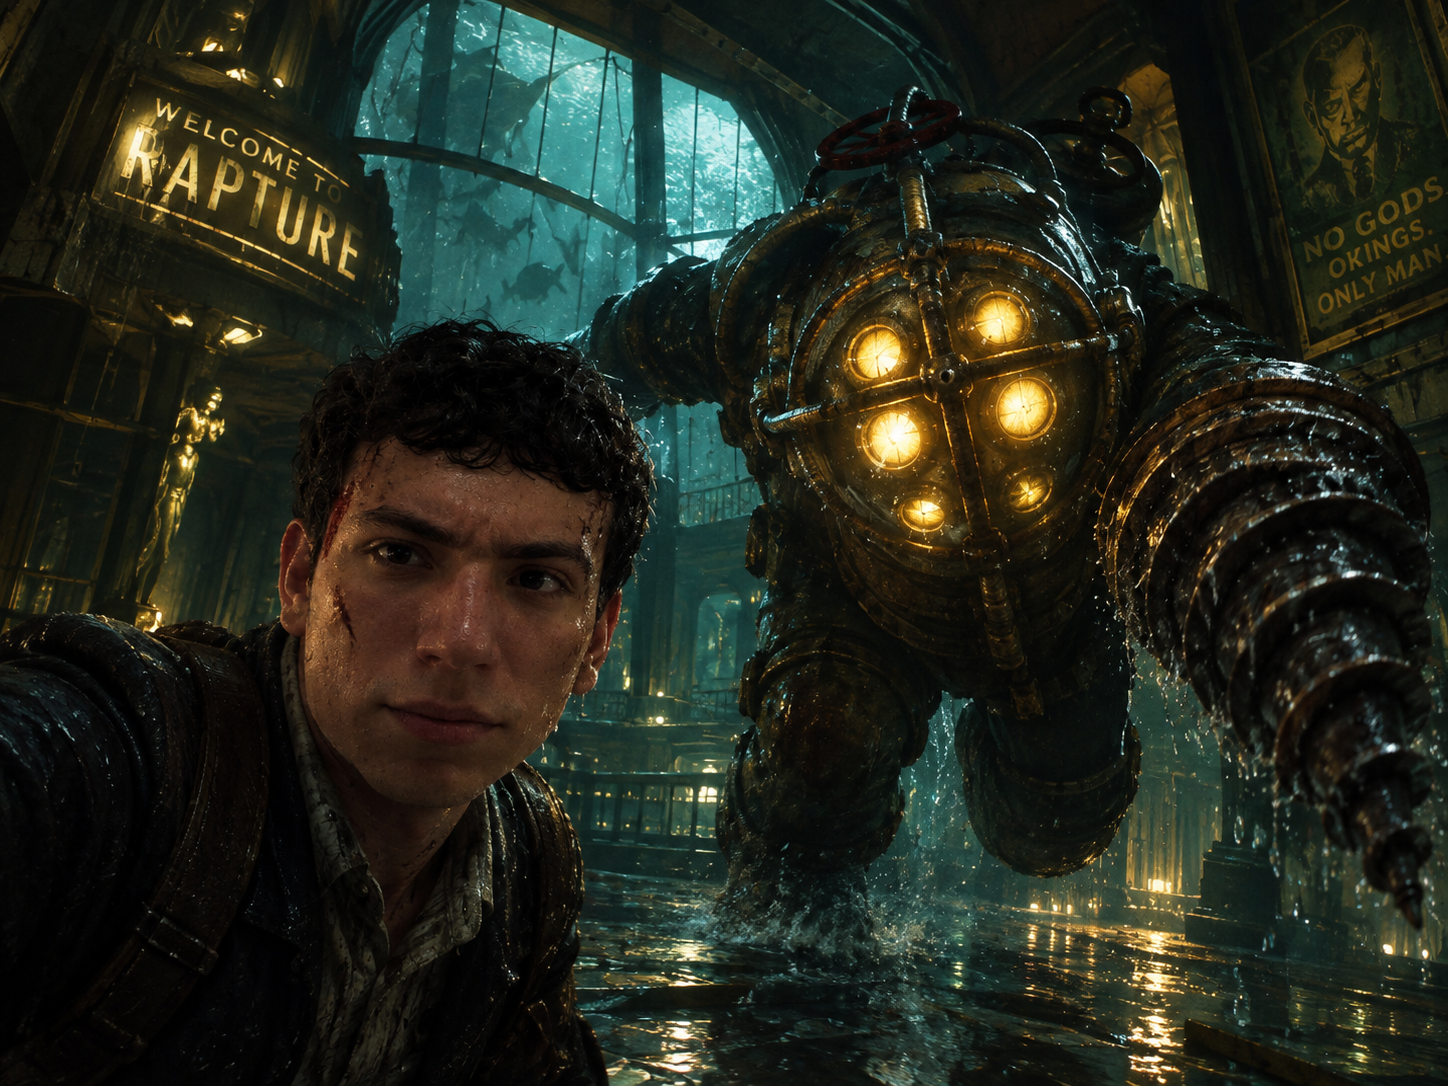

Nombre del alumno: Josue Raul Guerrero Peñaloza

Número de control: 24210583

Correo institucional: l24210583**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema2020_470P2_2')
parameters.StopTime = '15';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-2';
x = sim('sistema2020_470P2_2',parameters);

t_data = (0:0.1:15)';
t = (0:0.001:15)';
Pa = interp1(t_data, x.Pa, t, 'previous');

Pa =     0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420


writematrix(x.Pa, 'signal.xlsx');

## Respuesta en Individuos

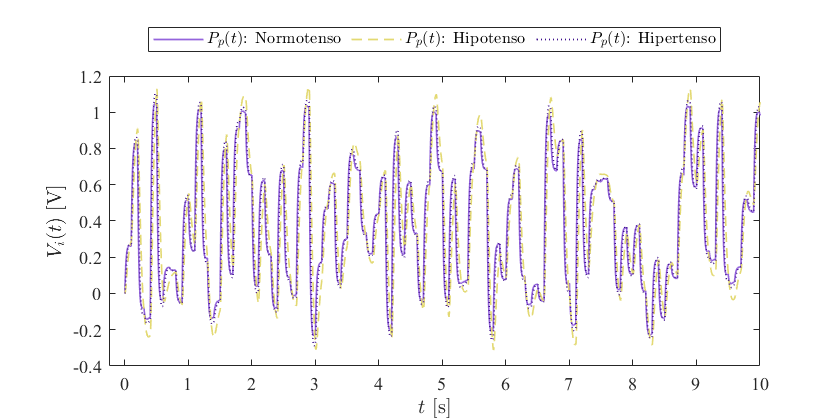

plotsignals(x.t,x.PpN,x.PpL,x.PpH,'Individuos')

## Respuesta: Normotenso, Hipotenso y Controlador

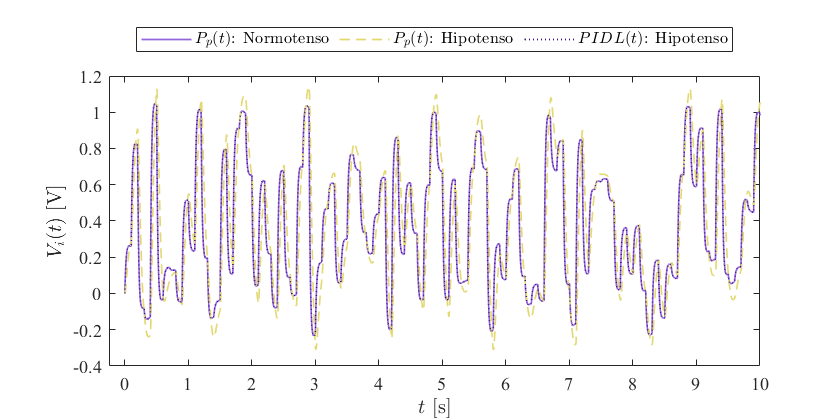

plotsignals(x.t,x.PpN,x.PpL,x.PIDL,'Hipotenso')

## Respuesta: Normotenso, Hipertenso y Controlador

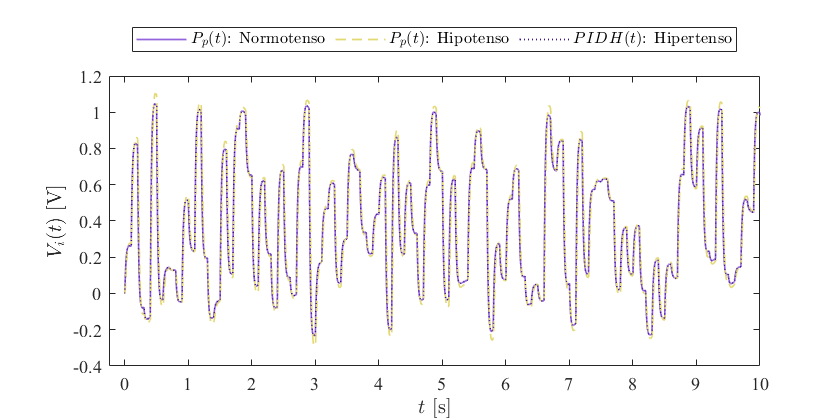

plotsignals(x.t,x.PpN,x.PpH,x.PIDH,'Hipertenso')

## Modelo de EDOs

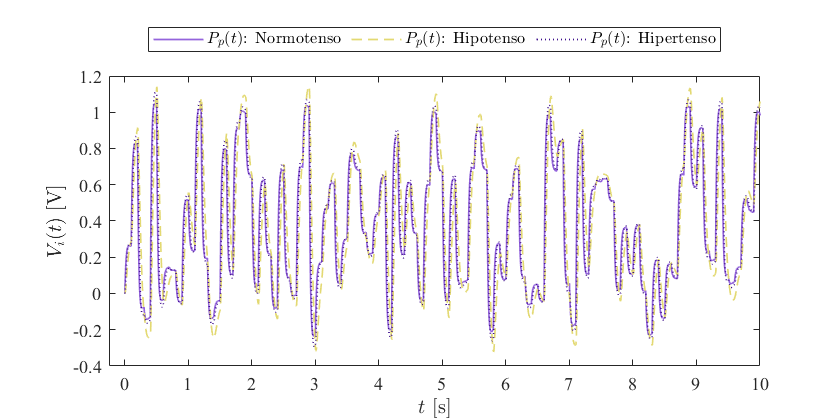

par_hipo = [0.01,0.001,1.00,3.500]; %[Z,L,R,C]
par_normo = [0.01,0.001,1.00,1.500];
par_hiper = [0.01,0.001,1.00,1.000];
PpN = cardio(par_normo,Pa,t);
PpL = cardio(par_hipo,PpN,t);
PpH = cardio(par_hiper,PpN,t);
plotsignals(t,PpN,PpL,PpH,'odes');

function Pp = cardio(par,Pa,t)
    Z = par(1); L = par(2); R = par(3); C = par(4); dt = t(2);
    n = round(t(end)/dt);
    FL = zeros(length(t),1); FL(1) = 0;
    Pp = zeros(length(t),1); Pp(1) = 0;
    for i = 1:n
        FL(i+1) = FL(i) + (-Pp(i)/L + Pa(i)/L)*dt;
        Pp(i+1) = Pp(i) + (FL(i)/C - (1/(Z*C) + 1/(R*C))*Pp(i) + Pa(i)/(Z*C))*dt;
    end
end

## Funcion: Respuestas de la simulacion

function plotsignals (t,x1,x2,x3,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = ([149, 100, 221])/256;
    clr2 = ([228, 218, 114])/256;
    clr3 = ([62, 15, 141])/256;
    order = [clr1;clr2;clr3]; colororder(order)
    xlabel('$t$ [s]','Interpreter','latex')
    ylabel('$V_i(t)$ [V]','Interpreter','latex')
    xlim([-0.25 10]); xticks(0:1:10)
  
    if signal == "Individuos"
        plot(t,x1,'-',t,x2,'--',t,x3,':','LineWidth',1)
        L = legend('$P_p(t)$: Normotenso','$P_p(t)$: Hipotenso','$P_p(t)$: Hipertenso');
    elseif signal == "Hipotenso"
        plot(t,x1,'-',t,x2,'--',t,x3,':','LineWidth',1)
        L = legend('$P_p(t)$: Normotenso','$P_p(t)$: Hipotenso','$PIDL(t)$: Hipotenso');      
    elseif signal == "Hipertenso"
        plot(t,x1,'-',t,x2,'--',t,x3,':','LineWidth',1)
        L = legend('$P_p(t)$: Normotenso','$P_p(t)$: Hipotenso','$PIDH(t)$: Hipertenso');
    elseif signal == "odes"
                plot(t,x1,'-',t,x2,'--',t,x3,':','LineWidth',1)
        L = legend('$P_p(t)$: Normotenso','$P_p(t)$: Hipotenso','$P_p(t)$: Hipertenso');
        
        
    end
    
    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)
    
    exportgraphics(gcf,[signal,'_matlab.pdf'],'ContentType','vector')
     
end